clear
rng(203829)
addpath('functions')
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];
plotPos2 = [100 100 800, 600];


kappa = 5*10^-5;
lambda = 3;
Lambda = 5*10^-5;
beta = 0.0065;
H = 0.05;

function x1 = F(t,x0)
    kappa = 5*10^-5;
    lambda = 3;
    Lambda = 5*10^-5;
    beta = 0.0065;
    H = 0.05;
    x1 = [
       (x0(3) - beta)/Lambda * x0(1) + lambda * x0(2);
       beta/Lambda * x0(1) - lambda * x0(2);
       -kappa*H*x0(1);
    ];
end

function JF = dF(t,x0)
    kappa = 5*10^-5;
    lambda = 3;
    Lambda = 5*10^-5;
    beta = 0.0065;
    H = 0.05;
    JF = [
       (x0(3) - beta)/Lambda,  lambda, lambda * x0(1);
       beta/Lambda, - lambda, 0;
       -kappa*H, 0, 0;
    ];
end



function B = G(t,x0)
    Lambda = 5*10^-5;
    B = [
        1/Lambda * x0(1);
        0;
        0;
    ];
end


C0 = [1,0,0];

dt = 10^-3

dt = 1.0000e-03

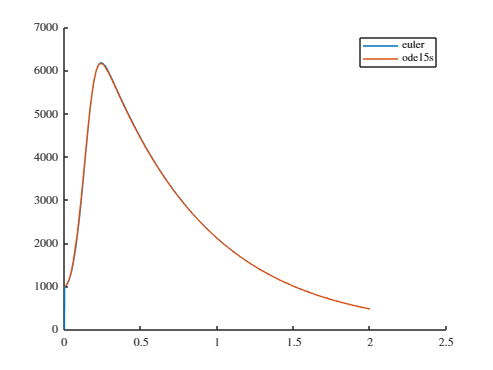

x0 = [1000,0,beta]';
% x0 = [0,0,0]';

Tfinal = 2;            % total simulation time [s]
Ts = dt;
N = round(Tfinal / dt);      % number of steps

x     = [x0,zeros(3, N)];   % true state
xhat  = zeros(3, N+1);   % estimated state
y     = zeros(1, N);     % measurements
yhat  = zeros(1, N);     % predicted outputs
u     = 0*ones(1, N);     % control inputs




for t = 1:N
    f = x(:,t) + F(t,x(:,t))*dt;
    g = G(t,x(:,t)) * dt;
    x(:,t + 1) = f + g * u(t);

    y(t + 1) = C0 * x(:,t + 1);

end



[t1,y1] = ode15s(@F,[0,(N+1)*Ts],x0);

figure()
hold on
plot((1:N+1)*Ts,y)
plot(t1',y1(:,1)')
legend("euler","ode15s")
hold off